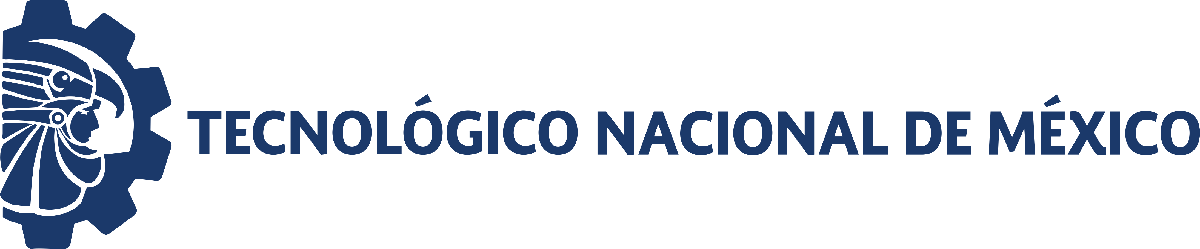                                 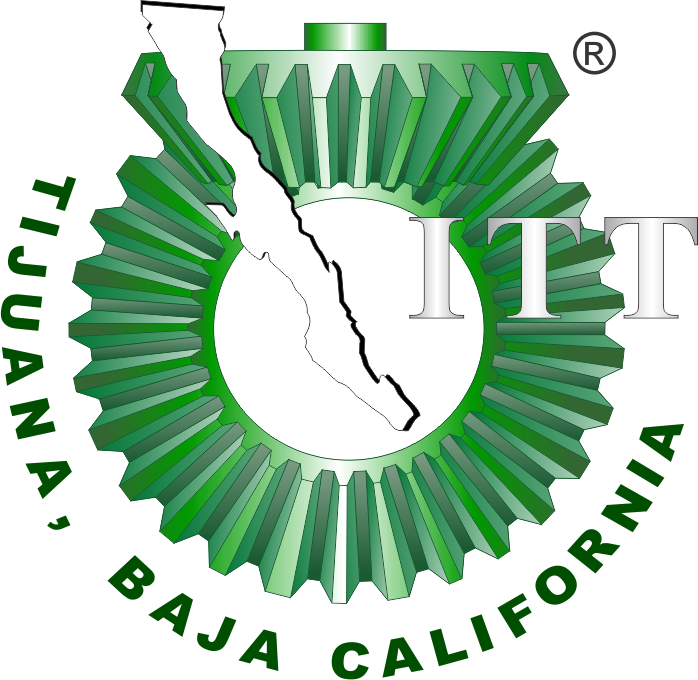

# Práctica Uno: Diseño de controladores

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

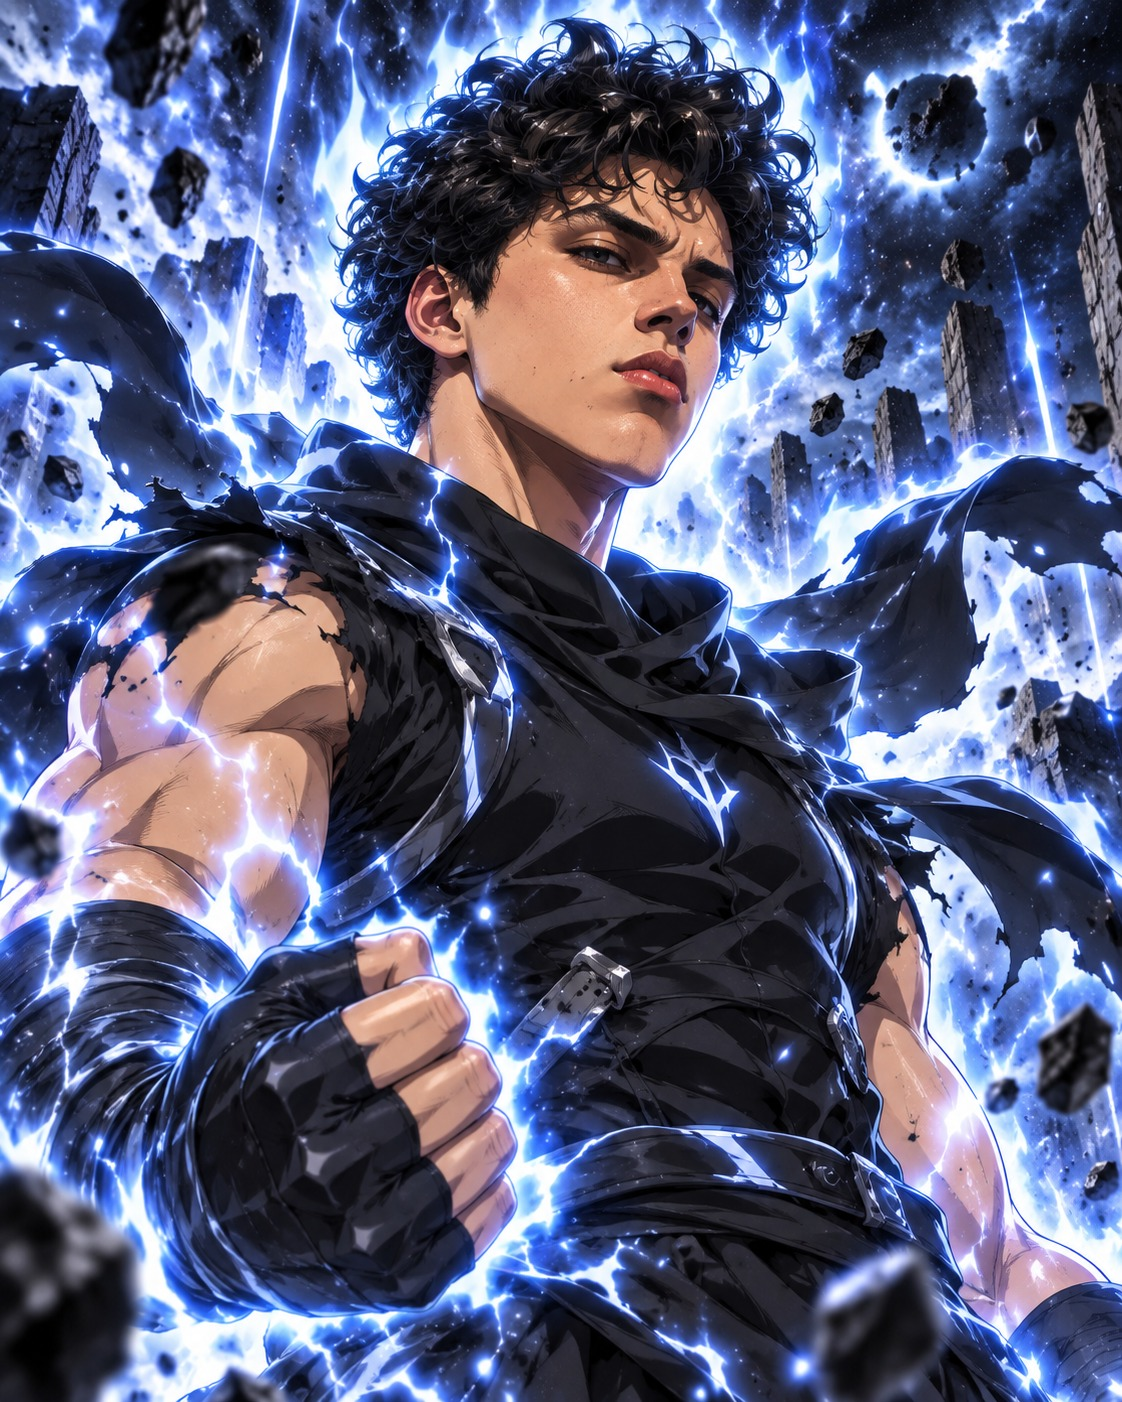

Nombre del alumno: Castro Alcántar Daniel Hiram

Número de control: **23212184**

Correo institucional: **l23212184@tijuana.tecnm.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('elsistema')
parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep ='1e-3';

## Respuesta al escalón

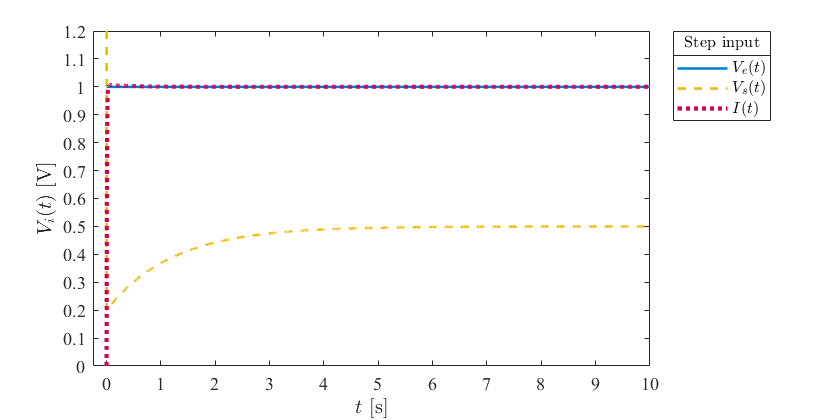

set_param('elsistema/S1','sw','1')
set_param('elsistema/Ve(t)','sw','1')
x1 = sim('elsistema',parameters);
plotsignals(x1.t,x1.Ve,x1.Vs,x1.I,'Step')

## Respuesta al impulso

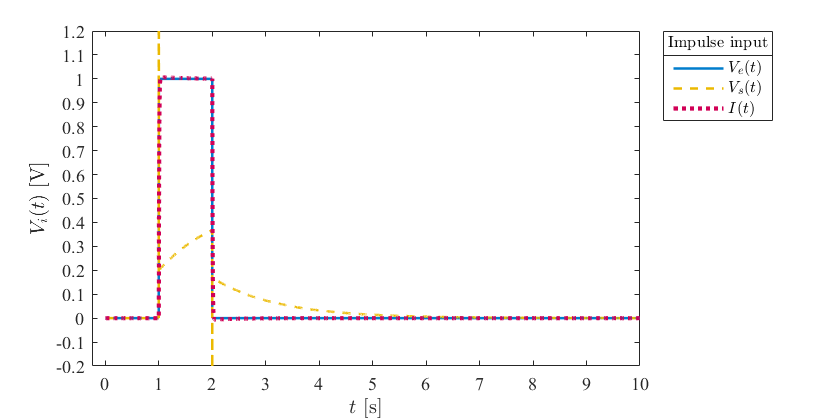

set_param('elsistema/S1','sw','0')
set_param('elsistema/Ve(t)','sw','1')
x2= sim('elsistema',parameters);
plotsignals(x2.t,x2.Ve,x2.Vs,x2.I,'Impulse')

## Respuesta a la rampa

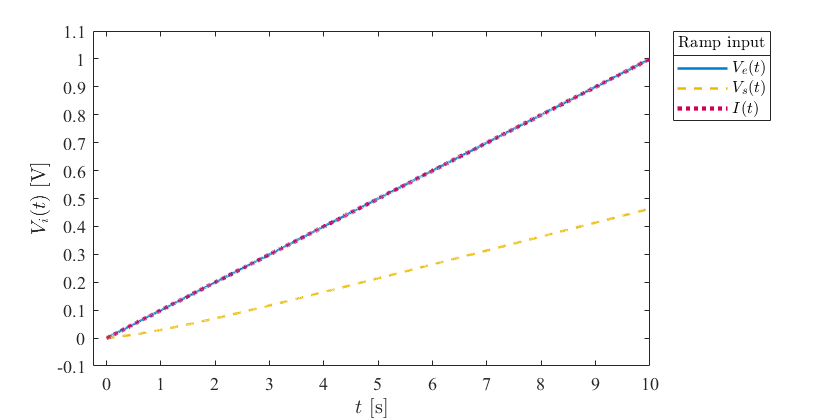

set_param('elsistema/S2','sw','1')
set_param('elsistema/Ve(t)','sw','0')
x4 = sim('elsistema',parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.I,'Ramp')

## Respuesta a la función sinusoidal

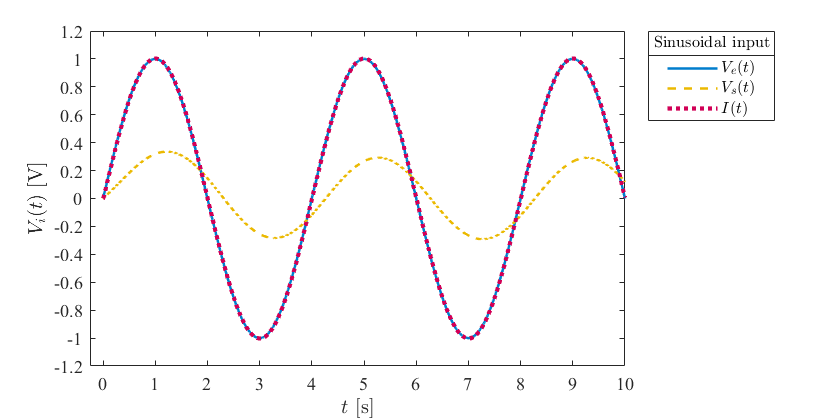

set_param('elsistema/S2','sw','0')
set_param('elsistema/Ve(t)','sw','0')
x4 = sim('elsistema',parameters);
plotsignals(x4.t,x4.Ve,x4.Vs,x4.I,'Sinusoidal')

## Funcion: Respuesta de la simulacion

function plotsignals(t,Ve,Vs,PID,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    ctrl1 = [0, 125, 204]/255;
    ctrl2 = [235,185,0]/255;
    ctrl3 = [209,0,86]/255;
    order = [ctrl1;ctrl2;ctrl3]; colororder(order)
    
    plot(t,Ve,'-','Linewidth',1.5,'Color',ctrl1)
    plot(t,Vs,'--','Linewidth',1.5,'Color',ctrl2)
    plot(t,PID,':','Linewidth',2.5,'Color',ctrl3)
    L = legend('$V_{e}(t)$','$V_{s}(t)$','$I(t)$');
    set(L,'interpreter','latex','location','northeastoutside',...
    'orientation','vertical')
    title(L,[signal,' ','input'])
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i (t)$ [V]','interpreter','latex')
    xlim([-0.25 10]); xticks(0:1:10)
    
    if signal == "Step"
        ylim([0 1.2]); yticks(0:0.1:1.2)
    elseif signal == "Impulse"
        ylim([-0.2 1.2]); yticks(-0.2:0.1:1.2)
    elseif signal == "Ramp"
        ylim([-0.1 1.1]); yticks(-0.1:0.1:1.1)
    elseif signal == "Sinusoidal"
        ylim([-1.2 1.2]); yticks(-1.2:0.2:1.2)    
    end

exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')

    

end